## 版本内容

仿真结果实验

## 仿真系统及DRL系统基本参数信息

### 仿真系统初始化

clc;clear;close all
warning('off')
addpath(genpath(pwd))
cfg = Simulink.fileGenControl('getConfig');
work_dir = pwd;
cfg.CacheFolder = fullfile(work_dir,'Simulation cache folder');
cfg.CodeGenFolder  = fullfile(work_dir,'Simulation cache folder');
Simulink.fileGenControl('setConfig', 'config', cfg);

### 工况

cyc_name = 'WLTC'; % CLTCP WLTC
switch cyc_name
    case 'CLTCP'
        load('CLTCP.mat');
        cyc_time =Cycle(:,1);
        cyc_vel =Cycle(:,2);
        clear Cycle
    case 'WLTC'
        load('WLTC.mat');
        cyc_time =WLTC(:,1);
        cyc_vel =WLTC(:,2);
        clear WLTC
end

### DRL采样时间

ts = 1;

### 发动机OOL参数

load("Eng_param")

### DRL观测空间物理范围

obs_max = 1e4*[0.0020, 0.0090, 0.0100, 0.0100, 8.4000, 0.0100,...
               0.0056, 0.1011, 2.8000,      0, 0.0001, 0.0132,...
               0.0740, 2.6065, 0.0339, 0.0949, 0.0117, 2.4444];
obs_min = 1e4*[0.0010, 0.0070,      0,      0, 0.8400,      0,...
                    0, -0.0005,     0, -2.8000,     0, -0.0032...
              -0.0694, -2.7092, -0.0030,    0, -0.0001, -2.7647];

### 奖励函数参数

rho_gas = 0.739;           % 95汽油密度 kg/L
Price_gas = 7.14;          % 92汽油油价 RMB/L
Price_elec = 1;            % 充电电价 RMB/kWh
k_gas = 1;                 % 油耗惩罚权重
k_elec = 1;                % 电耗惩罚权重
k_SOCpen = 3e-2;            % SOC惩罚权重
k_actsmo = 1e-2;           % action平滑性惩罚权重
rew_Zoom = 1;              % 奖励函数缩放系数
en_gas = 1;                % 油耗奖励参数使能
en_elec = 1;               % 电耗奖励参数使能
en_SOCpen = 1;             % SOC惩罚参数使能
en_actsmo = 1;             % 动作平滑惩罚参数使能
RBEMSEprew_ge = -9.88;     % WLTC 工况 Rule-Based EMS episode reward,油耗,电耗
RBEMSEprew_geS = -10.86;   % WLTC 工况 Rule-Based EMS episode reward,油耗,电耗,SOC惩罚
RBEMSEprew_geSa = -10.97;  % WLTC 工况 Rule-Based EMS episode reward,油耗,电耗,SOC惩罚，动作平滑

### 模型路径及DRL系统

mdl = "DRLHevIps";
VCU_Mode_Change(3)
VCU_Mode_2 = "DRLHevIps/xCU/xCU/VCU/Rule_Based_DataGen/DRL_EMS";
VCU_Mode_3 = "DRLHevIps/xCU/xCU/VCU/DRL_Based2_0/DRL_EMS";
agentblk = VCU_Mode_3;

### 模型运行时间

stop_time = cyc_time(end);

## 随机种子

previousRngState = rng(0,"twister");

## 创建env对象

obsInfo = rlNumericSpec([18 1], ...
                        LowerLimit=zeros(18,1), ...
                        UpperLimit=ones(18,1));
obsInfo.Name = "observation";
obsInfo.Description = "VCU Input";
actInfo = rlNumericSpec([1 1], ...
                        LowerLimit=-1,...
                        UpperLimit=1);
actInfo.Name = "action";
obsInfo.Description = "Eng Spd Mapping";
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);
env.UseFastRestart = "on";

## 创建 init DRL-EMS智能体

obs_dim = prod(obsInfo.Dimension);
act_dim = prod(actInfo.Dimension);

### Critic网络

obsPath = [
    featureInputLayer(obs_dim,Name="obsInLyr");
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); reluLayer(Name="obsPathOutLyr")];
actPath = [
    featureInputLayer(act_dim,Name="actInLyr");
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); reluLayer(Name="actPathOutLyr")];
commonPath = [
    concatenationLayer(1,2,Name="concat"); reluLayer;
    fullyConnectedLayer(512); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); reluLayer; fullyConnectedLayer(1)];

criticNet = dlnetwork;
criticNet = addLayers(criticNet,obsPath);
criticNet = addLayers(criticNet,actPath);
criticNet = addLayers(criticNet,commonPath);
criticNet = connectLayers(criticNet,"obsPathOutLyr","concat/in1");
criticNet = connectLayers(criticNet,"actPathOutLyr","concat/in2");
critic1 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo,...
    ActionInputNames="actInLyr",ObservationInputNames="obsInLyr");
critic2 = rlQValueFunction(initialize(criticNet),obsInfo,actInfo,...
    ActionInputNames="actInLyr",ObservationInputNames="obsInLyr");

### Actor网络

cPath = [
    featureInputLayer(obs_dim, Name="obsIn");
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer;
    fullyConnectedLayer(256); layerNormalizationLayer; reluLayer(Name="comOut")
    ];

% 均值分支
mPath = [
    fullyConnectedLayer(128,Name="mIn"); reluLayer; ...
    fullyConnectedLayer(act_dim,Name="mRaw"); ...
    tanhLayer(Name="meanOutLyr")];

% 标准差分支 (集成 ClipStdLayer)
stdMin = 0.05; stdMax = 1.0;
clipStd = @(x) min(max(x,stdMin),stdMax);

sPath = [
    fullyConnectedLayer(128,Name="sIn"); reluLayer; fullyConnectedLayer(act_dim,Name="sRaw"); ...
    softplusLayer; functionLayer(clipStd,Name="stdOutLyr",Formattable=true)];

actorNet = dlnetwork;
actorNet = addLayers(actorNet,cPath);
actorNet = addLayers(actorNet,mPath);
actorNet = addLayers(actorNet,sPath);
actorNet = connectLayers(actorNet,"comOut","mIn/in");
actorNet = connectLayers(actorNet,"comOut","sIn/in");
actor = rlContinuousGaussianActor(initialize(actorNet),obsInfo,actInfo, ...
    ActionMeanOutputNames="meanOutLyr", ...
    ActionStandardDeviationOutputNames="stdOutLyr", ...
    ObservationInputNames="obsIn");

### 创建智能体

criticOptions = rlOptimizerOptions( ...
    Optimizer="adam", ...
    LearnRate=7e-4, ...
    GradientThreshold=5, ...
    L2RegularizationFactor=1e-5);

actorOptions = rlOptimizerOptions( ...
    Optimizer="adam", ...
    LearnRate=5e-4, ...
    GradientThreshold=5, ...
    L2RegularizationFactor=1e-5);

agentOptions = rlSACAgentOptions(...
    SampleTime = ts, ...
    DiscountFactor = 0.99, ...
    TargetSmoothFactor = 1e-2, ...
    ExperienceBufferLength = 2e5, ...
    MiniBatchSize = 128, ...
    CriticOptimizerOptions = criticOptions, ...
    ActorOptimizerOptions = actorOptions);

% 配置自动熵调整
agentOptions.UseCriticTargetEntropy = true; 
agentOptions.EntropyWeightOptions.LearnRate = 5e-4; 

DRLEMSagent_init = rlSACAgent(actor,[critic1 critic2],agentOptions);

## 评估学习结果和过程

Agent_Mode = 3;
switch Agent_Mode
    case 1
        load(['Agent', num2str(296), '.mat'])
        trainResult = savedAgentResult;
        DRLEMSagent = saved_agent;
    case 2
        DRLEMSagent = DRLEMSagent_init;
    case 3
        load("DRLEMSagent.mat")
        load("trainResult.mat")
end

### 绘图

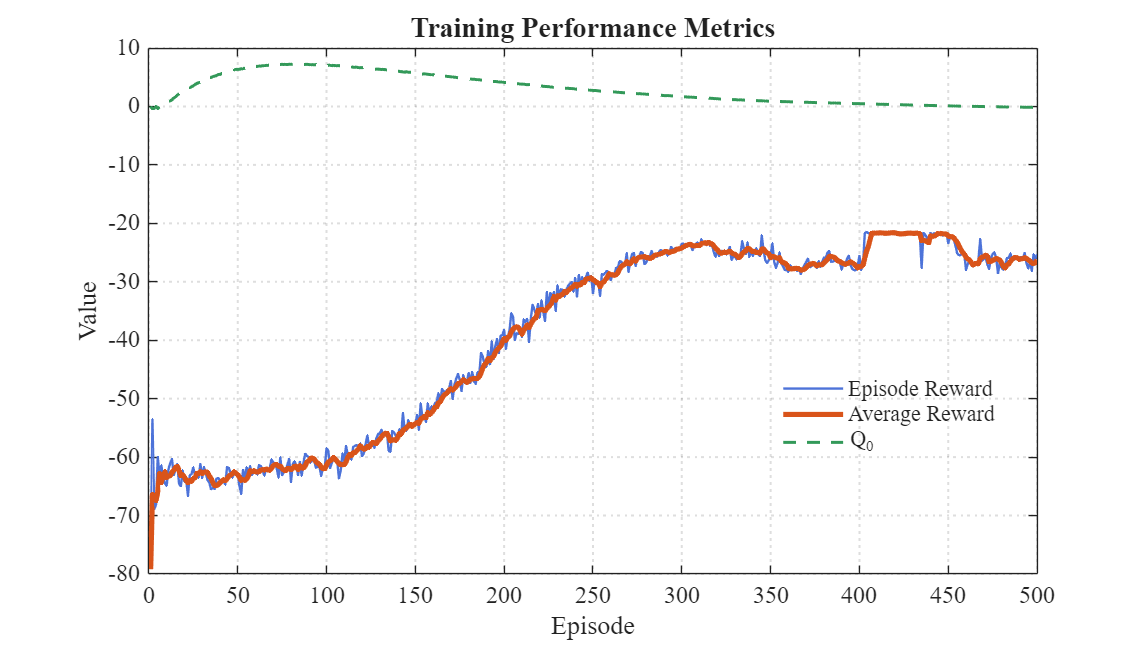

episode = trainResult.EpisodeIndex;
reward  = trainResult.EpisodeReward;
avgReward = trainResult.AverageReward;
steps = trainResult.EpisodeSteps;
totalSteps = trainResult.TotalAgentSteps;
q0 = trainResult.EpisodeQ0;
evalStat = trainResult.EvaluationStatistic;
figure('Color','w','Position',[200 200 800 450]);
hold on;
plot(episode, reward, ...
    'Color',[0.30 0.45 0.85], ...
    'LineWidth',1.2);
plot(episode, avgReward, ...
    'Color',[0.85 0.33 0.10], ...
    'LineWidth',2.6);

plot(episode, q0, ...
    'Color',[0.20 0.60 0.35], ...
    'LineStyle','--', ...
    'LineWidth',1.5);
hold off;
grid on;
box on;
set(gca, ...
    'FontName','Times New Roman', ...
    'FontSize',12, ...
    'LineWidth',1.0, ...
    'GridLineStyle',':');
xlabel('Episode','FontSize',13);
ylabel('Value','FontSize',13);
title('Training Performance Metrics','FontSize',14,'FontWeight','bold');
legend({'Episode Reward','Average Reward','Q_0'}, ...
       'Location','best', ...
       'Box','off', ...
       'FontSize',11);

### DRL-EMS env仿真

maxsteps = ceil(stop_time/ts);
simOptions = rlSimulationOptions(MaxSteps=maxsteps);
rng(previousRngState);
experience = sim(env,DRLEMSagent,simOptions);

### 正在模型 'DRLHevIps' 中搜索引用模型。
### 总共要构建 6 个模型。
### 启动串行模型编译。
### Bat 的模型引用仿真目标是最新的。
### ECU 的模型引用仿真目标是最新的。
### Eng 的模型引用仿真目标是最新的。
### Gen 的模型引用仿真目标是最新的。
### Mot 的模型引用仿真目标是最新的。
### VehPhy 的模型引用仿真目标是最新的。

编译摘要

编译了 0 个模型，共 6 个模型(6 个模型已经是最新的)
编译持续时间: 0h 0m 0.72882s


fprintf("单个episode奖励：%2f", sum(experience.Reward.Data));

单个episode奖励：-25.392345

### DRL-EMS simulink仿真

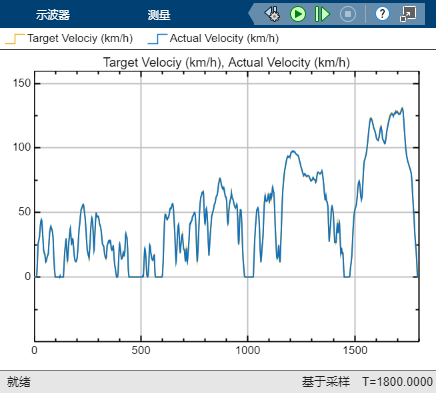

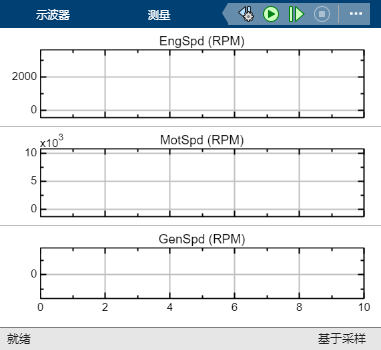

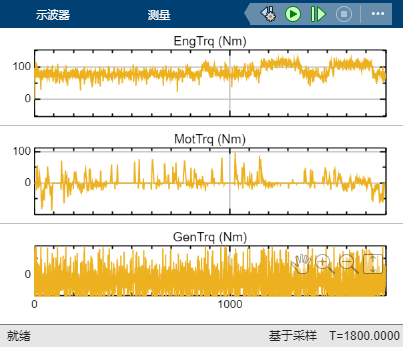

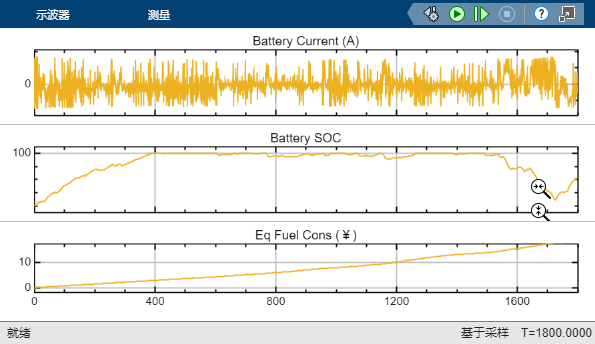

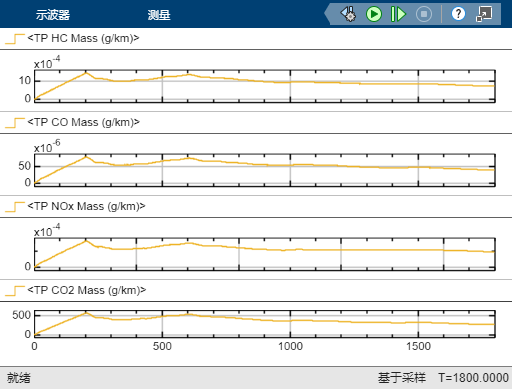

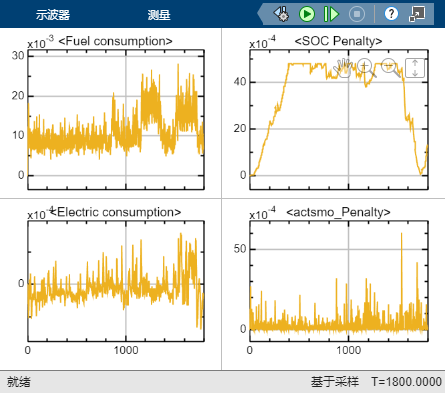

### 正在模型 'DRLHevIps' 中搜索引用模型。
### 总共要构建 6 个模型。
### 启动串行模型编译。
### Bat 的模型引用仿真目标是最新的。
### ECU 的模型引用仿真目标是最新的。
### Eng 的模型引用仿真目标是最新的。
### Gen 的模型引用仿真目标是最新的。
### Mot 的模型引用仿真目标是最新的。
### VehPhy 的模型引用仿真目标是最新的。

编译摘要

编译了 0 个模型，共 6 个模型(6 个模型已经是最新的)
编译持续时间: 0h 0m 9.0003s


load_system("DRLHevIps.slx")
open_system('DRLHevIps/Data Info/Operating condition signal')
open_system('DRLHevIps/Data Info/Power Element Rotation speed')
open_system('DRLHevIps/Data Info/Power Element Torque')
open_system('DRLHevIps/Data Info/Energy Signal')
open_system('DRLHevIps/Data Info/TP Emissions')
open_system('DRLHevIps/Data Info/Reward Single')
sim(mdl);

fprintf("DRL-EMS百公里等效经济成本￥/100km：%.2f\n", EqFuelCons_p100km(end));

DRL-EMS百公里等效经济成本￥/100km：78.97


### RB-EMS simulink仿真

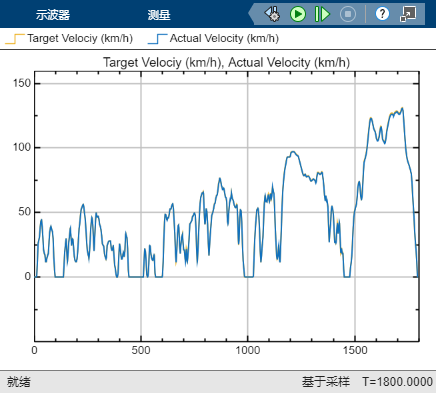

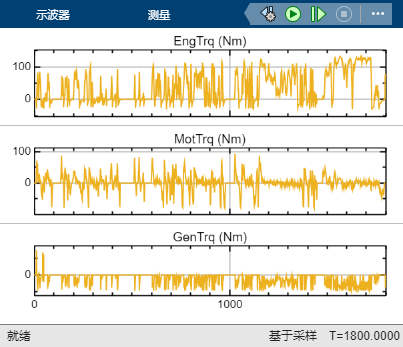

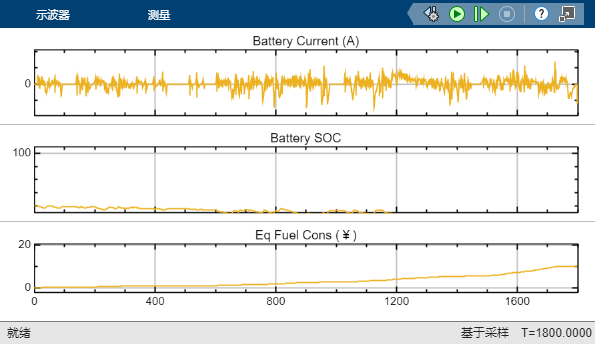

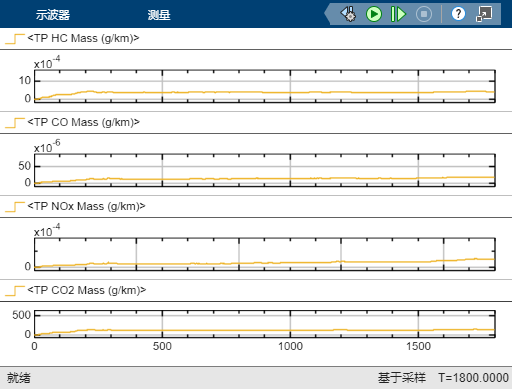

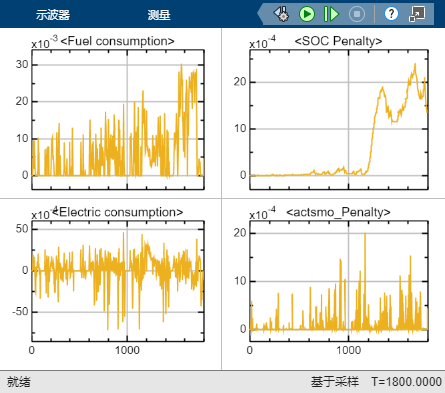

### 正在模型 'DRLHevIps' 中搜索引用模型。
### 总共要构建 6 个模型。
### 启动串行模型编译。
### Bat 的模型引用仿真目标是最新的。
### ECU 的模型引用仿真目标是最新的。
### Eng 的模型引用仿真目标是最新的。
### Gen 的模型引用仿真目标是最新的。
### Mot 的模型引用仿真目标是最新的。
### VehPhy 的模型引用仿真目标是最新的。

编译摘要

编译了 0 个模型，共 6 个模型(6 个模型已经是最新的)
编译持续时间: 0h 0m 0.49267s


VCU_Mode_Change(2)
load_system("DRLHevIps.slx")
open_system('DRLHevIps/Data Info/Operating condition signal')
open_system('DRLHevIps/Data Info/Power Element Rotation speed')
open_system('DRLHevIps/Data Info/Power Element Torque')
open_system('DRLHevIps/Data Info/Energy Signal')
open_system('DRLHevIps/Data Info/TP Emissions')
open_system('DRLHevIps/Data Info/Reward Single')
sim(mdl);

fprintf("RB-EMS百公里等效经济成本￥/100km：%.2f\n", EqFuelCons_p100km(end));

RB-EMS百公里等效经济成本￥/100km：42.61


function VCU_Mode_Change(param)
    HevIpsDictionaryObj = Simulink.data.dictionary.open('HevIps.sldd');
    HevIpsDataSectObj = getSection(HevIpsDictionaryObj, 'Design Data');
    signalObj = getEntry(HevIpsDataSectObj, 'VCU_Mode');
    signalValue = getValue(signalObj);
    signalValue.Value = param;
    setValue(signalObj, signalValue);
    saveChanges(HevIpsDictionaryObj);
end